# Esercitazione 10

Matlab has a precompile function implementing the Short Time Fourier Transform, *stft.m*. Use help command to study the function.

**1.Generate a chirp signal x(t), using the function *****chirp.m, *****at 1kHz, long 1s, initial frequency 20 Hz and final frequency 200 Hz. **

t=0:1/1000:1;           % Time reference vector
x=chirp(t,20,1,200);    % Chirp signal

**Apply the function on the signal x(t) and try to find the best configuration of the input (length of the window, overlap, window type, zero-padding) for obtaining a good compromise between frequency and time resolution.**

You can try the following configurations: 								

- length of the window 100 samples, no-zeropadding, no-overlap; 										

- length of the window 100 samples, no-zeropadding, overlap 50%; 										

- length of the window 100 samples, zeropadding 200 samples, overlap 50%; 									

- decrease the length of the window to 50 samples, zeropadding 1000 samples, overlap 50%; 									

- increase the length of the window to 200 samples, zeropadding 1000 samples, overlap 50%; 

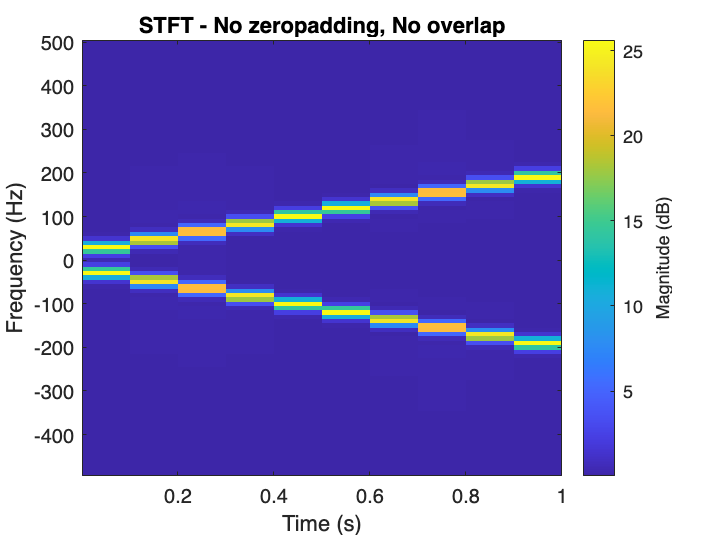

% Apply STFT with different window lengths, overlaps, and padding

% No zeropadding, no overlap
[s, f, t] = stft(x, 1000, 'Window', hamming(100), 'OverlapLength', 0);
figure;
imagesc(t, f, abs(s));
axis xy;
cb = colorbar;
ylabel(cb, 'Magnitude (dB)');
xlabel('Time (s)');
ylabel('Frequency (Hz)');
title('STFT - No zeropadding, No overlap');

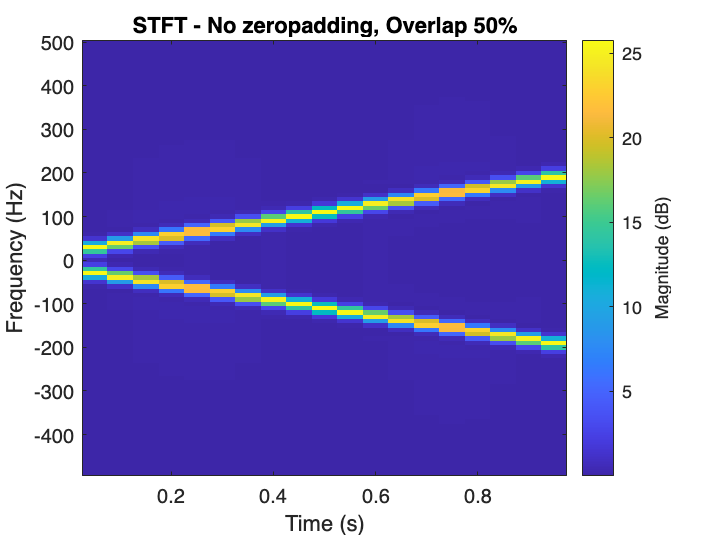


% No zeropadding, overlap 50%
[s, f, t] = stft(x, 1000, 'Window', hamming(100), 'OverlapLength', 50);
figure;
imagesc(t, f, abs(s));
axis xy;
cb = colorbar;
ylabel(cb, 'Magnitude (dB)');
xlabel('Time (s)');
ylabel('Frequency (Hz)');
title('STFT - No zeropadding, Overlap 50%');

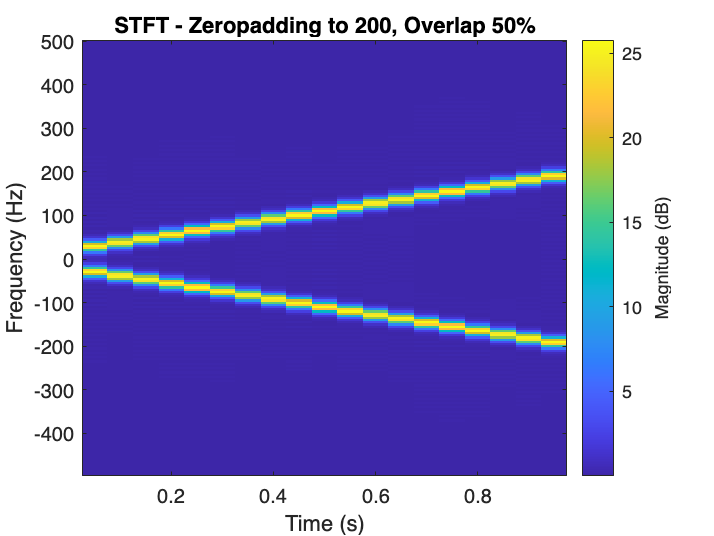


% Zeropadding to 200 samples, overlap 50%
[s, f, t] = stft(x, 1000, 'Window', hamming(100), 'OverlapLength', 50, 'FFTLength', 200);
figure;
imagesc(t, f, abs(s));
axis xy;
cb = colorbar;
ylabel(cb, 'Magnitude (dB)');
xlabel('Time (s)');
ylabel('Frequency (Hz)');
title('STFT - Zeropadding to 200, Overlap 50%');

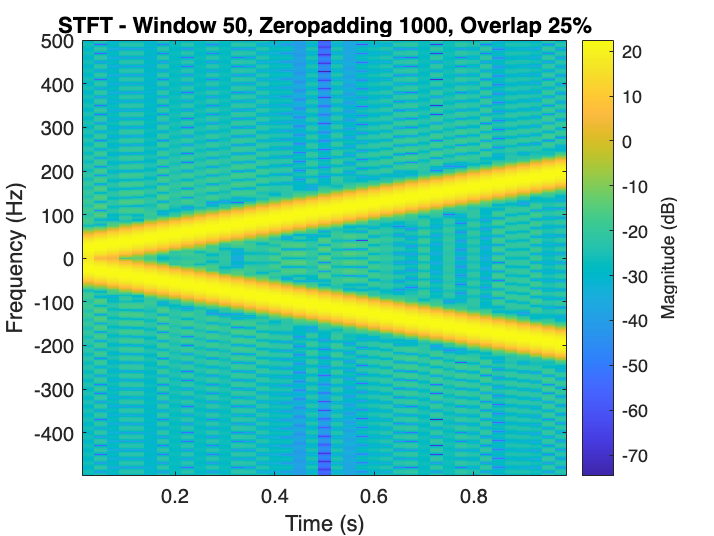



% Window length 50 samples, zeropadding 1000 samples, overlap 25%
[s, f, t] = stft(x, 1000, 'Window', hamming(50), 'OverlapLength', 25, 'FFTLength', 1000);
figure;
imagesc(t, f, 20*log10(abs(s)+eps));  % Display magnitude in dB
axis xy;
cb = colorbar;
ylabel(cb, 'Magnitude (dB)');
xlabel('Time (s)');
ylabel('Frequency (Hz)');
title('STFT - Window 50, Zeropadding 1000, Overlap 25%');

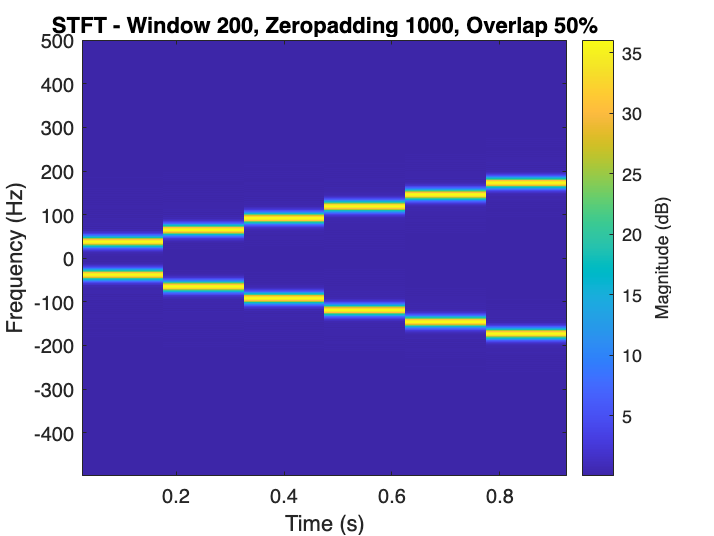



% Window length 200 samples, zeropadding 1000 samples, overlap 50%
[s, f, t] = stft(x, 1000, 'Window', hamming(200), 'OverlapLength', 50, 'FFTLength', 1000);
figure;
imagesc(t, f, abs(s));
axis xy;
cb = colorbar;
ylabel(cb, 'Magnitude (dB)');
xlabel('Time (s)');
ylabel('Frequency (Hz)');
title('STFT - Window 200, Zeropadding 1000, Overlap 50%');

**2. Load the signal *****emg.mat *****(fs = 1kHz).**

**Do the time-frequency analysis using the short-time fourier transform. **							**Comment the results in term of time and frequency resolution **

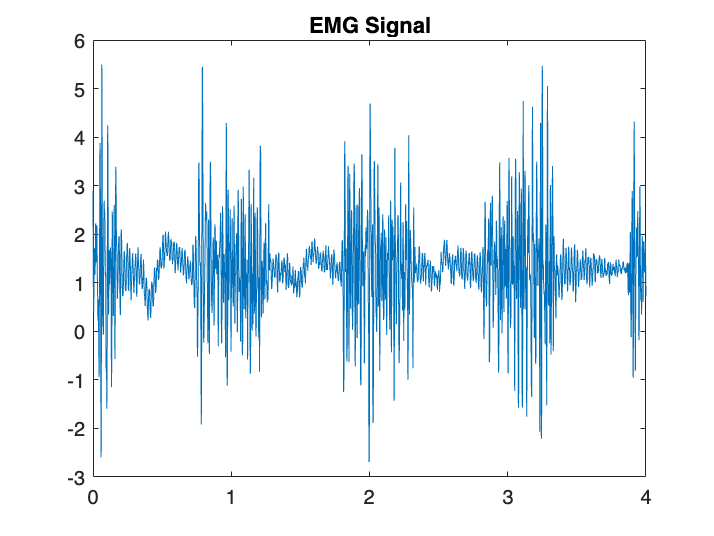

% Load the EMG signal
load('emg.mat');
emg = emg4;
fs = 1000;  % Sampling rate
t_emg = linspace(0, length(emg)/fs, length(emg));
figure;
plot(t_emg, emg);
title('EMG Signal');

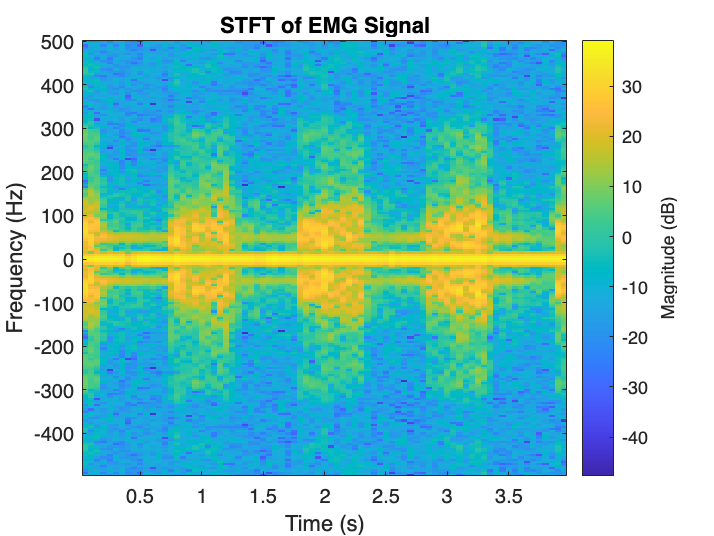


% Apply STFT on EMG signal
[s, f, t] = stft(emg, fs, 'Window', hamming(100), 'OverlapLength', 50, 'FFTLength', 200);
figure;
imagesc(t, f, 20*log10(abs(s)+eps));  % Display magnitude in dB
axis xy;
colorbar;
xlabel('Time (s)');
ylabel('Frequency (Hz)');
title('STFT of EMG Signal');
ylabel(colorbar, 'Magnitude (dB)');

**3. Segment the signal x(t) into segments lasting 200 samples. Estimate an AR model for any segment and create an autoregressive time-frequency representation. Apply both Yule-Walker and Burg techniques. Detail the following: **

**a. Estimated order for any segment **

**b. Variance of the residual series for any segment **

**c. Roots in the z-plane for any segment **

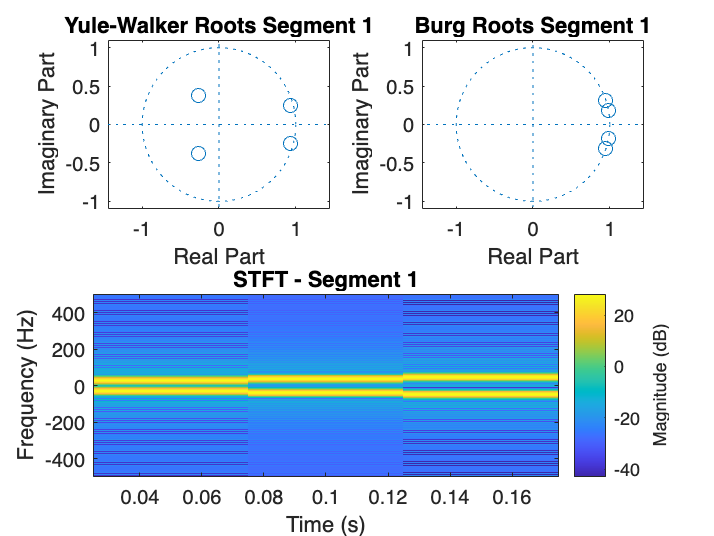

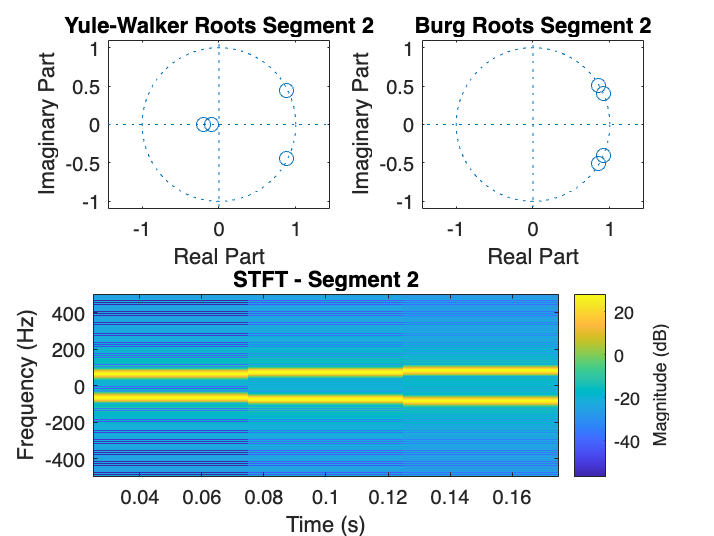

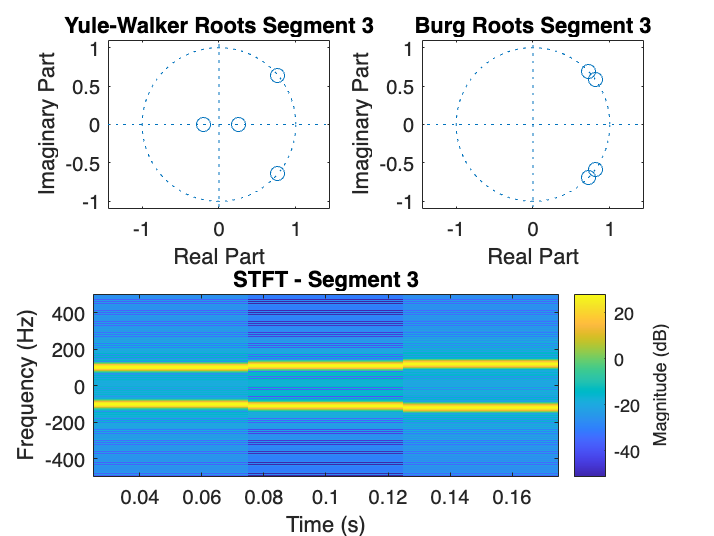

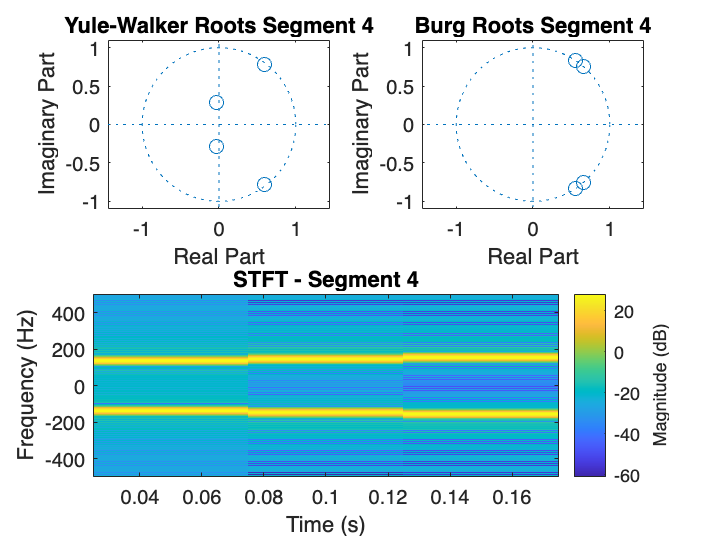

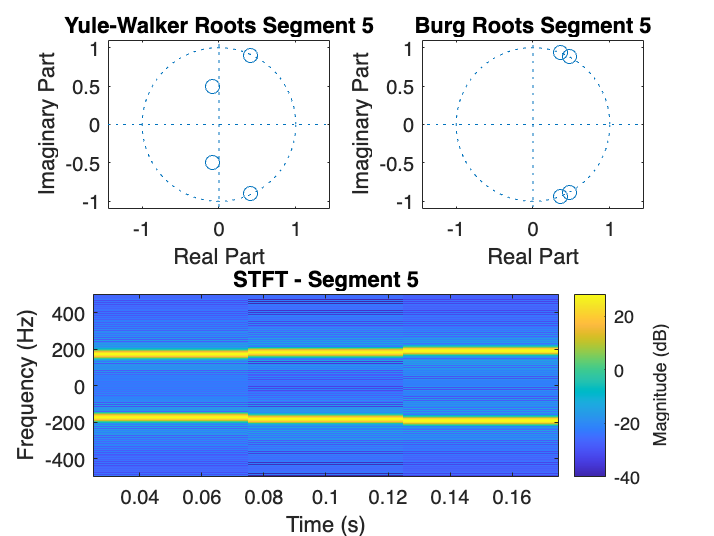

% Parameters
segment_length = 200;
N = length(x);  % Total length of the signal
number_of_segments = floor(N / segment_length);

% Initialize arrays to store data for each segment:
% AR orders, variance of residuals, and roots for each segment method
% Assuming AR order up to 4 for initial analysis
ar_order_yw = zeros(1, number_of_segments);
var_yw = zeros(1, number_of_segments);
ar_order_burg = zeros(1, number_of_segments);
var_burg = zeros(1, number_of_segments);

% Process each segment
for k = 1:number_of_segments
    % extract the k-th segment from the signal x
    segment = x((k-1)*segment_length + 1 : k*segment_length);
    
    % Yule-Walker AR model estimation
    % aryule function estimates the AR model parameters (coefficients) and the noise variance
    % Here, i use an order of 4 for the AR model as an assumption
    [ar_coeffs_yw, noise_var_yw] = aryule(segment, 4);
    roots_yw = roots(ar_coeffs_yw);
    ar_order_yw(k) = length(ar_coeffs_yw) - 1;  % AR order = coeff -1
    var_yw(k) = noise_var_yw;  % Variance of the residuals

    % Plotting Yule-Walker roots in the z-plane
    % zplane function plots the roots of the AR polynomial on the z-plane to visualize stability
    % Roots inside the unit circle indicate a stable system
    figure;
    subplot(2, 2, 1);
    zplane(roots_yw);
    title(sprintf('Yule-Walker Roots Segment %d', k));
    
    % Burg AR model estimation
    % arburg function similarly estimates AR model parameters and noise variance using the Burg method
    % This method can provide better spectral resolution for certain types of signals
    [ar_coeffs_burg, noise_var_burg] = arburg(segment, 4);
    roots_burg = roots(ar_coeffs_burg);
    ar_order_burg(k) = length(ar_coeffs_burg) - 1;  % AR order
    var_burg(k) = noise_var_burg;  % Variance of the residuals

    % Plotting Burg roots in the z-plane
    subplot(2, 2, 2);
    zplane(roots_burg);
    title(sprintf('Burg Roots Segment %d', k));

    % STFT analysis
    [s, f, t_stft] = stft(segment, 1000, 'Window', hamming(100), 'OverlapLength', 50, 'FFTLength', 400);
    
    % Plot STFT
    subplot(2, 1, 2);  % This uses the lower half of the figure for the STFT
    imagesc(t_stft, f, 20*log10(abs(s)+eps));  % Convert magnitude to dB
    axis xy;
    cb = colorbar;
    ylabel(cb, 'Magnitude (dB)');
    xlabel('Time (s)');
    ylabel('Frequency (Hz)');
    title(sprintf('STFT - Segment %d', k));
end

- **No Zero-padding, No Overlap (Window Length 100 samples)**

- This configuration offers a straightforward time-frequency representation without any overlap or padding, which can lead to faster computation but might compromise both time and frequency resolution due to windowing effects. This setup provides a basic view where spectral leakage and windowing artifacts could be more prominent due to the absence of overlap and padding.

- **No Zero-padding, 50% Overlap (Window Length 100 samples)**

- Introducing a 50% overlap increases the time resolution and helps to mitigate spectral leakage by averaging adjacent frames. This configuration improves the continuity and smoothness of the time-frequency representation but still lacks zero-padding, which might limit frequency resolution due to the unextended FFT computation.

- **Zero-padding to 200 samples, 50% Overlap (Window Length 100 samples)**

- Zero-padding extends the FFT length beyond the window length, improving frequency resolution by interpolating more points in the spectrum between the actual frequency bins. This setup enhances the ability to distinguish closely spaced frequencies while maintaining improved time resolution due to overlapping.

- **Window Length 50 samples, Zero-padding 1000 samples, 50% Overlap**

- Reducing the window length to 50 samples with significant zero-padding increases the frequency resolution drastically. The shorter window allows for finer time resolution, capturing rapid changes in the signal more accurately. However, extensive zero-padding may introduce more computational burden but provides a very detailed frequency analysis.

- **Window Length 200 samples, Zero-padding 1000 samples, 50% Overlap**

- Increasing the window length to 200 samples provides a broader view of each time segment, potentially smoothing out rapid changes but offering better noise handling and spectral leakage control. The significant zero-padding still ensures high frequency resolution, suitable for detailed spectral analysis where slower dynamics are of interest.

**Recommendations:**

- **For Detailed Frequency Analysis**: Choose configurations with higher zero-padding (e.g., zero-padding to 1000 samples), especially if the signal contains closely spaced frequency components.

- **For Capturing Fast Time Variations**: A shorter window length (e.g., 50 samples) with adequate zero-padding and overlap would be more appropriate.

- **Balanced View**: For a general-purpose analysis that balances time and frequency resolution without extensive computational demand, using a 100 samples window with 50% overlap and moderate zero-padding (e.g., 200 samples) might be optimal.